# Principal component analysis 主成分分析法

#### 已知有五个指标，现在要求以两个新的指标顶替这五个指标，依然能反映十个样本的全貌.

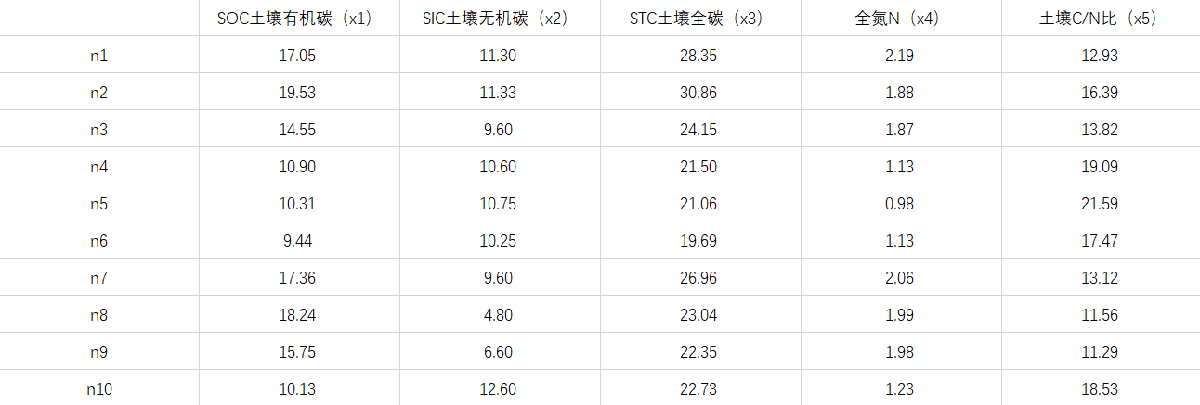

clear 
clc
x = [17.0500000000000	11.3000000000000	28.3500000000000	2.19000000000000	12.9300000000000
19.5300000000000	11.3300000000000	30.8600000000000	1.88000000000000	16.3900000000000
14.5500000000000	9.60000000000000	24.1500000000000	1.87000000000000	13.8200000000000
10.9000000000000	10.6000000000000	21.5000000000000	1.13000000000000	19.0900000000000
10.3100000000000	10.7500000000000	21.0600000000000	0.980000000000000	21.5900000000000
9.44000000000000	10.2500000000000	19.6900000000000	1.13000000000000	17.4700000000000
17.3600000000000	9.60000000000000	26.9600000000000	2.06000000000000	13.1200000000000
18.2400000000000	4.80000000000000	23.0400000000000	1.99000000000000	11.5600000000000
15.7500000000000	6.60000000000000	22.3500000000000	1.98000000000000	11.2900000000000
10.1300000000000	12.6000000000000	22.7300000000000	1.23000000000000	18.5300000000000];

## 代码

% 计算样本协方差矩阵
[N_sample, P_target] = size(x)

N_sample = 10

P_target = 5

n = N_sample

n = 10

p = P_target

p = 5

R = corrcoef(x)

R =     1.0000   -0.4137    0.7991    0.9112   -0.7482
   -0.4137    1.0000    0.2167   -0.4261    0.6656
    0.7991    0.2167    1.0000    0.6957   -0.3628
    0.9112   -0.4261    0.6957    1.0000   -0.9126
   -0.7482    0.6656   -0.3628   -0.9126    1.0000



% 计算协方差矩阵的特征值和特征向量
[value, vector] = eig(R)

value =     0.6668    0.1420    0.4972    0.1464   -0.5162
    0.4106    0.0725   -0.4897    0.7124    0.2808
   -0.6219    0.2001    0.2098    0.6274   -0.3681
   -0.0000   -0.7734   -0.3442    0.0509   -0.5299
   -0.0000   -0.5799    0.5920    0.2735    0.4882


vector =     0.0000         0         0         0         0
         0    0.0083         0         0         0
         0         0    0.2231         0         0
         0         0         0    1.3308         0
         0         0         0         0    3.4378


value = rot90(value)'

value =    -0.5162    0.1464    0.4972    0.1420    0.6668
    0.2808    0.7124   -0.4897    0.0725    0.4106
   -0.3681    0.6274    0.2098    0.2001   -0.6219
   -0.5299    0.0509   -0.3442   -0.7734   -0.0000
    0.4882    0.2735    0.5920   -0.5799   -0.0000


lambda = diag(vector)

lambda =     0.0000
    0.0083
    0.2231
    1.3308
    3.4378


lambda = lambda(end:-1:1)

lambda =     3.4378
    1.3308
    0.2231
    0.0083
    0.0000



%计算贡献率和累计贡献率
contribution_rate = lambda ./ sum(lambda)

contribution_rate =     0.6876
    0.2662
    0.0446
    0.0017
    0.0000


accumulate_contribution_rate = cumsum(lambda) ./ sum(lambda)

accumulate_contribution_rate =     0.6876
    0.9537
    0.9983
    1.0000
    1.0000



% accumulate_contribution_rate > 0.85
% 且尽量指标越少的作为主成分，即前两个，选出主成系数
K = min(find(accumulate_contribution_rate > 0.80))

K = 2

disp('***********************')

***********************


disp('Result: ')

Result: 


M = value([1:K],:)'

M =    -0.5162    0.2808
    0.1464    0.7124
    0.4972   -0.4897
    0.1420    0.0725
    0.6668    0.4106


## 新指标$y_1
$和$y_2$代替原来五个指标，满足如下函数关系

### 
$$y_1=-0.5162x_1+0.1464x_2+0.4972x_3+0.1420x_4+0.6668x_5$$


### 
$$y_2=0.2808x_1+0.7124x_2-0.4897x_3+0.0725x_4+0.4106x_5$$
